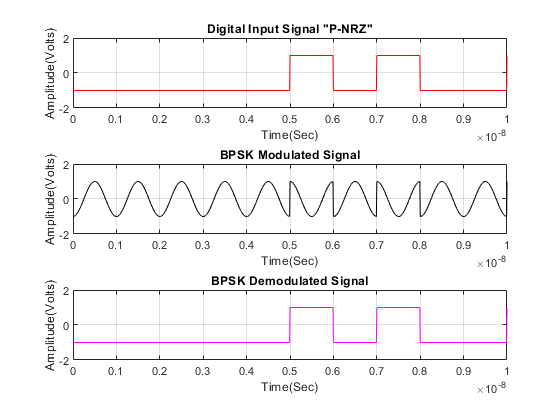

clear
fc=1e9;
ac=1;
Tb=1/fc;
no_of_bit=100;             
nsc=100;
tsc=1e-11;
T=no_of_bit*Tb; %1e-7
tc=0:tsc:Tb-tsc;
c=cos(2*pi*fc*tc);
line_code=randi([0 1],1,no_of_bit);
data=line_code*2-1;      
tm=linspace(0,T,10000);
N=ceil(T/tsc);                  %Normalization
df=1/T;                        %frequency step
fs=1/tsc;                       %sampling frequency
if (rem(N,2)==0)               %if normalization even number 
   f=-(0.5*fs):df:(0.5*fs-df); 
else                           %if normalization even number 
   f=-(0.5*fs-0.5*df):df:(0.5*fs-0.5*df);
end

counter=0;
for i=1:100
    if data(i)==1
        for q=1:100
            P_NRZ(q+counter)=data(i);
        end
    else 
        for q=1:100
            P_NRZ(q+counter)=data(i);
        end
    end
    counter=counter+100;
end
clear counter , q;
figure
subplot(3,1,1);
plot(tm,P_NRZ,'r');
grid on;
axis([0 1e-8 -2 2]);
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title('Digital Input Signal "P-NRZ"');
modulated = [];
for i=1:100
    if data(i)==1
        y = ac*cos(2*pi*fc*tc+0);   % Modulation signal with carrier signal 1
    else 
        y = ac*cos(2*pi*fc*tc+pi);  % Modulation signal with carrier signal 0
    end
    modulated=[modulated y]; 
end
subplot(3,1,2);
plot(tm,modulated,'black');
xlabel('Time(Sec)');
ylabel('Amplitude(Volts)');
title('BPSK Modulated Signal');
grid on
axis([0 1e-8 -2 2]);
% ********************* Channel model h and w *****************************
h = 1;   
w = 0;   
% ********************* Received signal y *********************************
noise_signal = h.*modulated + w;   
% *************************** BPSK Demodulation ***************************
demodulated = [];
for n = 100:100:length(modulated)
  c = cos(2*pi*fc*tc);                 
  mm = c.*noise_signal((n-(100-1)):n);   
  z = trapz(tc,mm);                    
  if(z > 0)                        
    a = 1;
  else
    a = -1;
  end
  demodulated = [demodulated a];
end
 %%%%%%%%%%%%%%%%%% Represent demodulated information as digital signal %%%%%%%%%%%%%%%%%%
 counter=0;
 for i=1:100
     if demodulated(i)==1
         for q=1:100
             RX_P_NRZ(q+counter)=demodulated(i);
         end
     else
         for q=1:100
              RX_P_NRZ(q+counter)=demodulated(i);
        end
     end
     counter=counter+100;
 end
 subplot(3,1,3)
 plot(tm,RX_P_NRZ,'m');
 grid on
 xlabel('Time(Sec)');
 ylabel('Amplitude(Volts)');
 title('BPSK Demodulated Signal');
 axis([0 1e-8 -2 2]);

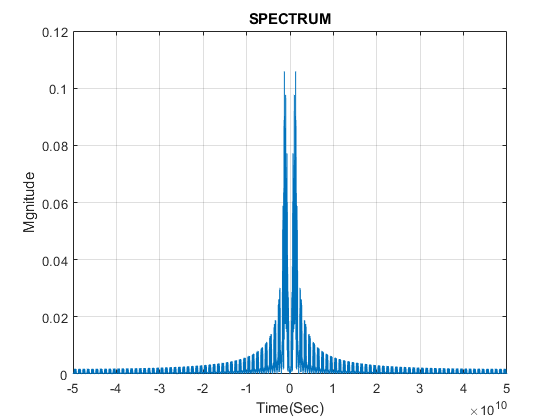

 %%%%%%%%%%%%%%%%%%%%%%%%% BER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 no_bit_error_P_NRZ=0;                                
 for i=1:length(RX_P_NRZ)                             
     if(P_NRZ(i)~=RX_P_NRZ(i))                        
         no_bit_error_P_NRZ=no_bit_error_P_NRZ+1;     
     end                                              
 end                                                  
 no_bit_error_P_NRZ=no_bit_error_P_NRZ/nsc;           
 BER_P_NRZ=no_bit_error_P_NRZ/no_of_bit;               
 % ********************* SPECTRUM signal x ******************************
 figure
 plot(f,abs(fftshift(fft(modulated))/N))
 xlabel('Time(Sec)');
 ylabel('Mgnitude');
 title('SPECTRUM');
 grid on

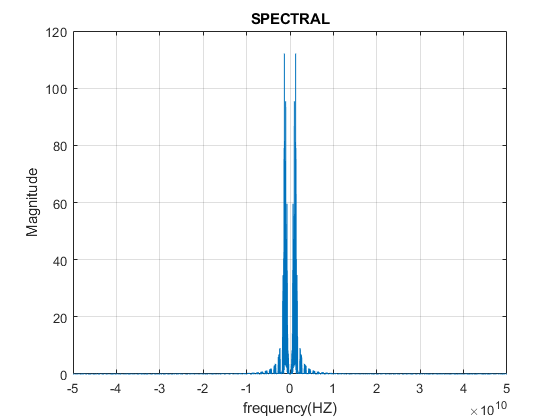

 % ********************* SPECTRAL signal x ******************************
 figure
 plot(f,(abs(fftshift((fft(modulated)))).^2/N))
 xlabel('frequency(HZ)');
 ylabel('Magnitude');
 title('SPECTRAL');
 grid on